R=OurRobot;

Library folder added to path: C:\Users\16178\Documents\WPIStuff\classes\Robotics\501\RobotDynamics\mr
valid mlist


model(R.mlist);
Task=Task1Functions(R);

format short
TA=Task.FindTFromPosAndAngle([.185,-.185,.185]')

TA =          0    0.7071   -0.7071    0.1850
         0    0.7071    0.7071   -0.1850
    1.0000         0         0    0.1850
         0         0         0    1.0000


TB=Task.FindTFromPosAndAngle([.185,.170,.070]')

TB =          0   -0.6766   -0.7363    0.1850
         0    0.7363   -0.6766    0.1700
    1.0000         0         0    0.0700
         0         0         0    1.0000


out=Task.FindTransformations(TA,TB)

out =     1.0000         0         0   -0.1150
         0    0.0422   -0.9991    0.2510
         0    0.9991    0.0422    0.2510
         0         0         0    1.0000



test=zeros(4,4,3);
test(:,:,1)=[eye(4)];


test(:,:,2)=TB

test = test(:,:,1) =

     1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


test(:,:,2) =

         0   -0.6766   -0.7363    0.1850
         0    0.7363   -0.6766    0.1700
    1.0000         0         0    0.0700
         0         0         0    1.0000


test(:,:,3) =

     0     0     0     0
     0     0     0     0
     0     0     0     0
     0     0     0     0


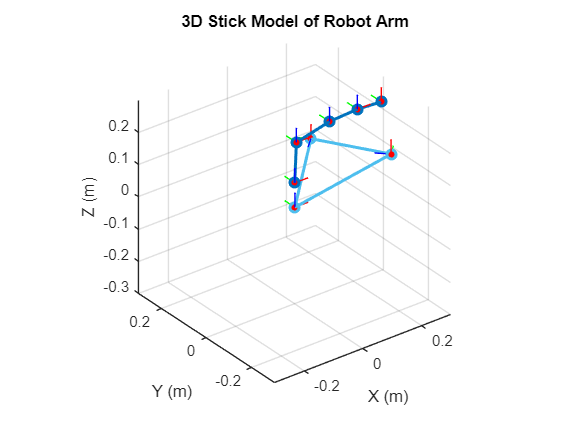


model(test);

test(:,:,2)=TA;
test(:,:,3)=out;


model(test);